# Computing cross-sectional area changes from height and width observations

Mike Durand, durand.8@osu.edu

May 22, 2018

## 1. Introduction

Cross-sectional area is of primary importance in river hydraulics. Repeat measurements of height and width are possible from space, and made increasingly routinely. Heights and widths can inform an estimate of time variations in cross-sectional area, but not not the cross-sectional area itself.

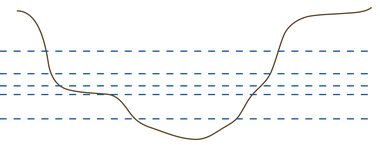

For example, in the figure above, imagine the blue lines are observations of height and width cutting through a river cross section. You can use trapezoidal approximations to estimate the area above the lowest observation, but not the final cross-sectional area below the lowest observation.

Change in cross-sectional area is a SWOT data product, and is one of the terms in the Manning equation for discharge algorithms. In the past, we have not had a standard definition for how exactly area changes will be calculated, or the precise way they will be defined. This document is a proposal for the change in cross-sectional area algorithms for SWOT, and also have relevance elsewhere. I'm suggesting we reference everything to the timeseries median water surface elevation, and to median cross-sectional area. This has several advantages over existing methods, as explained below.  

## 2. Definitions

The water surface elevation timeseries $H_t$ can be written as the sum of the time-series median $\bar{H}$ and the zero-median time varying-part ${H}\prime_t$, as is the top river width $W_t$:

$H_t=\bar{H}+{H}\prime_t$, $W_t=\bar{W}+{W}\prime_t \qquad (1) $        

Note that medians are used throughout, rather than means, as these timeseries tend to be non-Gaussian, and means are affected by one or two large values at high flow. In general, as height increases, so does width. Looking at the sketch above, it should be clear that for any observed  $H_{min} \leq H_t \leq H_{max}$, you could calculate:


$$A_t (H_t)= A(H_{min}) + \int_{H_{min}}^{H_t} f_W(H)dH \qquad (2)$$
    

where $f_W(H)
$is a function relating width and height, and $A(H_{min}) $ is the cross-sectional area below the minimum height observation.  We can call this the partial cross-sectional area measurement by elevation and widths (PACMEW?). This was presented in Durand et al. (2014). The key elements are the time-varying part, and a constant. 

However referencing to the minimum height is not the most convenient definition; heights are noisy, so how do you tell which is really the minimum? Also every time you get a new pass, you have a new possibility to redefine the minimum. In fact, to minimize bookkeeping, the current MetroMan redefines the first term in eqn. (2) to be the cross-sectional area of the first observation in the timeseries. BAM uses the "minimum" definition. Neither of these are great for data products, however. 

Here, I am proposing using a variant of eqn. (2), defined in terms of the median river elevation of the timeseries. Instead of leaving us a minimum $A_0$ or a "first" cross-sectional area to estimate, we have the median cross-sectional area as the unknown, which is arguably easier to get prior information on. Define cross-sectional area as was done for height and width:


$$A_t=\bar{A}+{A}\prime_t \qquad (3)$$
    

There is a complication here that Renato reminded me of while I was working on this, so we'll call it Renato's Reminder: assuming that the cross-section is not rectangular, then the relationship between width and height when integrated is most likely non-linear. So evaluating the second term on the right-hand side of equation 2 at $\bar{H}$ will not give you $\bar{A}$; there will be a slight mis-match, which will not vary in time, that we will call $\varepsilon_{\bar{A}}$. So we have this:


$$A_t (H) = \bar{A} + \varepsilon_{\bar{A}} + \int_{\bar{H}} ^{H} f_W(H')dH'  \qquad  (4)$$


Equation (4) just says that you can estimate the cross-sectional area for a particular cross-section by its median $\bar{A}$, an integral over a height-width function integrated from the median water surface elevation $\bar{H}$ to a particular measured height $H$, combined with a temporally-constant error due to the non-linearity in the integrated $f_W$ function. The third term on the right of equation (4) comes out to exactly zero at $\bar{H}$. Both of the first two terms on the RHS of (4) are time-invariant, so can be estimated together. From a practical standpoint, $\bar{A} \gg \varepsilon_{\bar{A}}$ for the cases I've looked at, and so we can apply prior information about $\bar{A}$ on the sum without much error. It may seem surprising that one does not need an explicit integration from $H_{min}$ up to $H$. In fact, however, $A \prime$ can be estimated by integrating starting at any point along the $f_W(H)$ curve; it's just a matter of definitions, and the meaning of the time-invariant part of the RHS of (4). Note though that $f_W(H)$ must be defined from $H_{min}$ to $H_{max}$.

This is all borne out by an example case, below. The technical algorithm details are described further down. This work divides neatly into two parts: Computing $f_W$ based on a set of height-width data, and computing $A\prime$using $f_W$. As discussed later, for SWOT, these two tasks would be done "offline" by the Science Team, and "online" as part of the SWOT processing chain, respectively. They are described in Sections 5 and 6, respectively.

clear all; close all

addpath('./PepsiSrc');

## 3. Setup: Read data and create synthetic observations

So far, I've just looked at example cases on the Sacramento Upstream (cf=13), Garonne Downstream  (cf=4), and the Seine (cf=14) from the Pepsi 1. Once this code is implemented in RiverObs, we will test using simulator data output on the Sacramento, Garonne, Tanana, Platte, Amazon, and St. Lawrence. All plots shown in the live script here are from the Garonne Downstream.

cf=4;
pathtoncfiles='./Pepsi1/';
Files=dir([pathtoncfiles '*.nc']);
numbfiles=size(Files,1);
ReadRiver;
FilterRiver;
R=Rivers(cf).Reaches; 
disp(['Working with: ' Rivers(cf).Name ' data.'])

Working with: Seine data.


tObs=ceil(Rivers(cf).orbit./86400)';
nObsCycle=length(tObs);
clear Rivers

There are two options here: either the "SWOT observations" or "Perfect observations". Note that it's helpful if choosing the "perfect" option to have some tiny amount of error, as some of the methods assume error covariances exist. The SWOT observations samples the timeseries to SWOT times. Note this is a so-called Matlab Live Script, a ripoff of Python notebooks: code and report are presented side-by-side. I will get the whole package of code and test case shared ASAP. Email me if you want access.


[nR,nt]=size(R.W);
t=1:nt;

% SWOT observation
nCycle=floor(nt/21);
nReg=3; %number of regions
for i=2:nCycle
    tObs=[tObs tObs(1:nObsCycle)+(i-1)*21];
end
nObs=length(tObs);


## 4. Visualize height-width relationship 

Here we pick a reach to look at, and visualize heights and widths. Fig. 1 shows the true height-width relationship at the observed times.

r=3;

disp(['Working with reach ' num2str(r)])

Working with reach 3


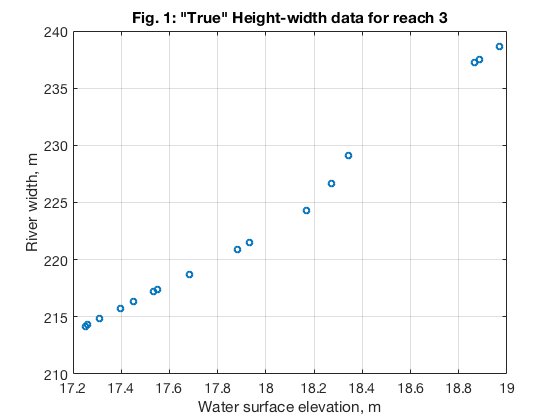


figure(1)
plot(R.H(r,tObs),R.W(r,tObs),'o','LineWidth',2); 
set(gca,'FontSize',14)
xlabel('Water surface elevation, m')
ylabel('River width, m')
title(['Fig. 1: "True" Height-width data for reach ' num2str(r)])
grid on

## 5. Fitting funtions to the width & height data

What should the form of $f_W$ be? The simplest solution would be to perform ordinary least squares regression on width vs height. There are several problems with this. First, height-width relationships often change over the height domain, e.g. when rivers flood their banks; therefore more than one sub-domain might be preferable, with different relationships in each sub-domain. A continuous piecewise-linear function meets these requirements. Second, both the heights and widths have errors in them; ordinarly least squares does not account for the errors in the independent variable (height, in this case). This can be easily resolved with the so-called ["Errors in Variables" model](https://en.wikipedia.org/wiki/Errors-in-variables_models) (Fuller, 2006). Third, it's not clear where to define the boundaries of the sub-domains. This can be fairly easily done by an optimization routine choosing to minimize square errors by choosing different sub-domain boundaries; note that the optimization can be done off-line in determining the sub-domains, and thus would not be part of the SWOT processing chain. Fourth, outliers can easily skew these types of calcuations, so we should do some outlier analysis as part of these steps. Fifth, it seems a shame to use only height or only width when calculating each estimate of $A \prime$. Fortunately, the Errors in Variables (EIV) allows one to use both.

A few details on the EIV model are probably useful. The linear, scalar EIV model with known width and height measurement error standard deviations $\sigma_W$and $\sigma_H$ respectively, can be found by choosing slope and intercept $p_1$and $p_2$, respectively to minimize $(\sigma_W^2 + p_1^2 \sigma_H^2)^{-1} {\sum_t (p_1 H_t + p_2 - W_t)^2 $, where the "t" subscritps indicate the various observations of a particular reach. This objective function comes directly from Fuller's equation 1.3.20, combined with the assumption that there is no correlation between errors in height and width. The term behind the summation is the objective function to minimize for ordinary least squares estimation of a first-order polynomial. Fuller shows that ignoring the height uncertainty basically biases the slope towards zero (see his eqn. 1.1.6); we underestimate the slope between height and width if we don't include the first term in parentheses in the objective function above. Note that the objective function is still a very simple model. There are far more interesting models in Fuller that can be used to estimate the actual measurement errors affecting a particular sample. In principle, we could use non-linear functions to represent the height-width curves for each reach. However, these reaches must be fit on all of ~350,000 global reaches, so simplicity is good. Additionally, it's not clear that non-linear fits would significantly improve performance. We will assume piece-wise linear, for now.

The next challenge is to find the best "sub-domain boundaries" or breakpoints in the height-width data. This can be done relatively simply. I borrowed some inspiration from John D'Errico's [Shape Language Modeling](https://www.mathworks.com/matlabcentral/fileexchange/24443-slm-shape-language-modeling) toolbox (I wanted to use his code but couldn't as he did not have an EIV option). Basically though you end up with the following optimization problem:


$$\min_{H_b, p} \sum_{s=1}^{n_s} (\sigma_W^2 + p_{s,1}^2 \sigma_H^2)^{-1} {\sum_{j} (p_{s,1} H_j + p_{s,2} - W_j)^2 \qquad (5)$$



$$\text{subject to:} \quad  p_{s,1} H_{b,s+1} + p_{s,2} = p_{s+1,1} H_{b,s+2} + p_{s+1,2}, \quad s=1...n_{s}-1$$


where $n_s$ is the number of sub-domains, $H_{b,s}$ for $s=1...n_s+1$ are the breakpoints or sub-domain boundaries defined in terms of their river height (note that these include start and end points), and $p_{s,1}$ and $p_{s,2}$ are the slopes and intercepts for each sub-domain. The constraint requires the piece-wise linear $f_W$ functions to meet at breakpoints. I additionally found it necessary to require that $H_{b,s}$ be monotonically increasing. I found that using three sub-domains, and thus having four values of $H_b$, was adequate for the data I have looked at so far. 

Note that it is not fully clear what values to use for $\sigma_H$ and $\sigma_W$. Error models are still under formulation for the data products, but are complicated by the fact of correlated errors among the nodes used to compute reach averages. The height error can be approximated using the error budget. The width error budget is excessively conservative for wide rivers, so values could be used based on instrument simulator studies. As a final option, one could always try to back out these parameters from the EIV model, by e.g. adding a term to the objective function based on the difference between fit error and the data standard deviations.

In order to handle outliers, I treated just the most obvious case, which showed up in the Sacramento: one or sometimes two heights falling far higher than the rest. Other cases can be added, though aren't in this logic, yet. What I do for now is if a high outlier is detected, I require the third value of $H_b$ to be equal to the maximum value of the heights excluding outliers. 

Note that everything in this section is what the Science Team would do; the fit parameters needed for the $A \prime$ calculations would be included in the a priori database. Note that $A \prime$would thus not be calculated for the first year of mission operations, as the $f_W$ functions would not yet be defined.

ReDoFits=true;
if ReDoFits
    stdH=0.1;
    stdW=10;
    Hobs=R.H(:,tObs)+stdH.*randn(nR,nObs);
    Wobs=R.W(:,tObs)+stdW.*randn(nR,nObs);
    Hbar=median(Hobs,2);
    Wbar=median(Wobs,2);
    
    disp('Re-computing fits. This takes a while...')
    
    for i=1:nR  %fit H-W functions
        disp(['Computing fit for reach ' num2str(i) '/' num2str(nR)])
        SpecialCases{i} = CheckSpecialCases(Wobs(i,:),stdW);
        if SpecialCases{i}.LowWidthVar
            p{i}{1}=[0 mean(Wobs(i,:))]; p{i}{2}=[]; p{i}{3}=[]; p{i}{4}=[];
            xbreak{i}=[min(Hobs(i,:)) max(Hobs(i,:)+1E-4) nan nan];
            iout{i}=false(size(Wobs(i,:)));
            [hval{i},wval{i}]=TestEvaluation(Hobs(i,:),xbreak{i},p{i},nReg);
            UseReg{i}=[1 0 0 ];
        else
            [p{i},xbreak{i},iout{i},hval{i},wval{i}]=CalcWHFitsEIV(Hobs(i,:),Wobs(i,:),nReg,stdH,stdW);       
            UseReg{i}=[1 1 1];
        end
    end
    save('WHFits.mat','p','xbreak','iout','hval','wval','Hobs','Hbar','Wobs','Wbar','stdH','stdW','UseReg')
else
    load WHFits.mat
end

Re-computing fits. This takes a while...


Computing fit for reach 1/4
Computing fit for reach 2/4
Computing fit for reach 3/4
Computing fit for reach 4/4


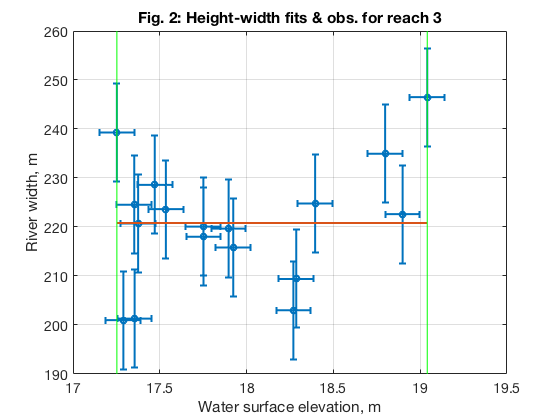


m_zz=nan(2,2,nR);  %m_zz is the W-H observation covariance matrix for each reach
for i=1:nR    
    m_zz(:,:,i)=cov(Wobs(i,:),Hobs(i,:));
end

figure(2)
errorbar(Hobs(r,:),Wobs(r,:),stdW*ones(nObs,1),stdW*ones(nObs,1),stdH*ones(nObs,1),stdH*ones(nObs,1),'LineStyle','none','LineWidth',2,'Marker','o'); hold on
plot(hval{r},wval{r},'LineWidth',2)
a=axis;
for i=1:length(xbreak{r})
    plot(xbreak{r}(i)*ones(2,1),a(3:4),'g-')
end
plot(Hobs(r,iout{r}),Wobs(r,iout{r}),'kx','MarkerSize',12,'LineWidth',2)
hold off;
set(gca,'FontSize',14)
xlabel('Water surface elevation, m')
ylabel('River width, m')
title(['Fig. 2: Height-width fits & obs. for reach ' num2str(r)])
grid on

In some cases, such as reach 5 on the Sacramento upstream with 10 m width error standard deviation, the algorithm effectively chooses only two sub-domains, by choosing two boundaries very close to one another. This is not a problem, and the $A\prime$calculations are robust to this special case.

There are a number of possible special cases. For example, the Seine has very low width variability. To address this, we check for whether the width variance is a certain amount greater than the width error variance. If not, we simply assume the channel is rectangular, and use only one sub-domain.

## 6. Performing the$A \prime$calculations 

Once the above fits and breakpoints are done by the Science Team, the fit data (breakpoints, slopes, etc.) would be supplied to the space agencies producing the data for online computation of $A \prime$. At JPL, the acronym for that software is the "Science Data System" (SDS). How will ${A}\prime_t$ be computed? As mentioned, it is probably ideal to use both the height and width observation at a given time to do this calculation. The EIV approach allows you to do this by basically combining the height and width observations to map onto an optimal height-width point on the fit line. The optimal height point on that line $\hat{H}_t$ is given by:


$$\hat{H_t} = H_t + \left( \sigma_W^2 + p_1^2 \sigma_H^2\right)^{-1} \left(p_1 \sigma_H^2 \right) (W_t - p_2 - p_1 H_t)  \quad (6)$$


where if you look close, you'll see a lot of similarity with the Kalman update equation, which makes sense, as both consider uncertainties in dependent and independent variables, and both are so-called ["BLUE" estimators](https://en.wikipedia.org/wiki/Gauss–Markov_theorem). Note that I did not include the "sub-domain" notation in equation (6) as it gets tedious. (There is a small chance that by updating $H_t$ to $\hat{H}_t$, you end up moving a height point from one sub-domain to another, so I added a check for that, and re-do equation (6), if it happens).

The final step is to actually integrate the $f_W$ functions. For a particular estimate $\hat{H_t}$ that falls within sub-domain $d$:


$$A\prime_t(\hat{H_t}) = \sum_{s=1}^{d-1} \int_{H_{b,s}}^_{H_{b,s+1}} \left( p_{s,1} H + p_{s,2} \right)dH + \int_{H_{b,d}}^_{\hat{H_t}} \left( p_{d,1} H + p_{d,2} \right)dH- A\prime( \bar{H} ) \qquad (7)$$
 

where $A \prime( \bar{H} )$ is the difference from median cross-sectional area at $\bar{H}$. It can be computed by applying equation (7) evaluated at $\bar{H}$, but ommitting the final term. 

You can see a plot of $A\prime(H)$ for a particular reach, in Fig. 3. The "true" circles are defined by computing the true cross-sectional area (as that is available for Pepsi Challenge rivers), and computing the anomaly using equation (3). The red line evaluates equation (7) at a series of height values, in a sort of "offline" mode without using width observations. The function is quadratic in shape which makes sense given that it's an integral of a first order polynomial. The SWOT estimated $A\prime(H)$ curve passes through the data, but with a small offset: the "Renato's Reminder" term $\varepsilon_{\bar{A}}$ takes a value printed to screen, usually on the order of 10 m^2. (This error is estimated by interpolating the true height-area curve to the median height, i.e.: $\varepsilon_{\bar{A}} = A\prime(\bar{H})-\bar{A}$.)  Note that the $\bar{H}$ is plotted against an $A\prime$ value of zero, but does not exactly overlap with the blue points (i.e. the true $A\prime$). However,$\varepsilon_{\bar{A}}$ is generlaly small compared to true $\bar{A}$.

dAHbar=CalculatedAEIV(Hbar(r),Wbar(r),xbreak{r},p{r},nReg,0,stdW^2,stdH^2,m_zz(:,:,r),nObs); %sample calculation

rMax=find(UseReg{r}, 1, 'last' );

Htest=linspace(xbreak{r}(1)+.001,xbreak{r}(rMax+1)-.001,100);

for i=1:length(Htest)
    [dAtest(i),Wtest(i)] = CalculatedAEIV(Htest(i),[],xbreak{r},p{r},nReg,dAHbar,stdW^2,stdH^2,m_zz(:,:,r),nObs); %sample calculation
end

[~,iSort]=sort(R.H(r,:));
[Hs,iUnique]=unique(R.H(r,:),'sorted');
As=R.A(r,iUnique);
AHbarhat_true=interp1(Hs,As,Hbar(r));

epsilonAbar=AHbarhat_true-median(R.A(r,:));

disp(['epsilon_Abar='  num2str(epsilonAbar) ' m^2'])

epsilon_Abar=8.5476 m^2


disp(['Abar='  num2str(median(R.A(r,:))) ' m^2'])

Abar=1256.8441 m^2


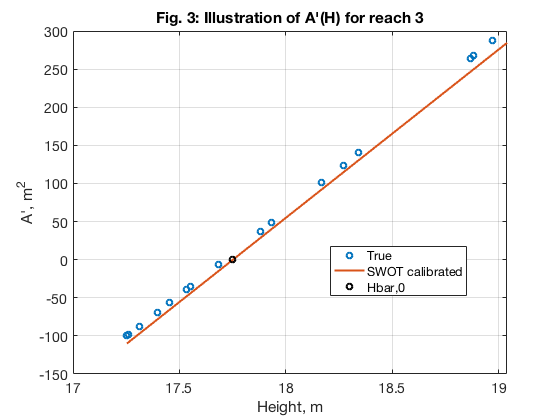


dAtrue=R.A(r,:)-median(R.A(r,:)); %true dA for comparison

figure(3)
plot(R.H(r,tObs),dAtrue(tObs),'o',Htest,dAtest,Hbar(r),0,'ko','LineWidth',2)
set(gca,'FontSize',14)
xlabel('Height, m')
ylabel('A'', m^2')
legend('True','SWOT calibrated','Hbar,0','Location','Best')
grid on;
title(['Fig. 3: Illustration of A''(H) for reach ' num2str(r)])

## 7. Timeseries estimation of $A\prime$ and preliminary uncertainty calculations

Uncertainty is a bit gnarly for constrained optimization problems, and the sub-domain issue makes this complicated, too. I put some time into this, and got as a far as a simple EIV estimate for the slopes; even that I had to take shortcuts (see Appendix). Then the final uncertainty estimate on $A\prime$ I could not get to work out well. So for now, I implemented a very simple approach, assuming half of the error variance in the estimator comes from the height error, and that you can approximate the response of $A\prime$ to height error using the Durand et al. (2014) way of computing $A\prime$. Under these assumptions you get:


$$\sigma_{A\prime} = W \sigma_H \sqrt{2} \qquad (8)$$


I hope to revisit this, and so have included four additional parameters to be passed into the SDS (see below). 

Another challenge is what to do when an observation falls outside the range that the data were fit on. I think in this case the best we can do is use the simple trapezoidal approximation of $A\prime$between the nearest sub-domain boundary, and compute the associated uncertainty so that is what I've implemented, though not yet tested.

Once this is all done, you get the timeseries and uncertainty shown in Fig. 4. You can see that overall, things look pretty good, except for the uncertainty bars for $A \prime$.

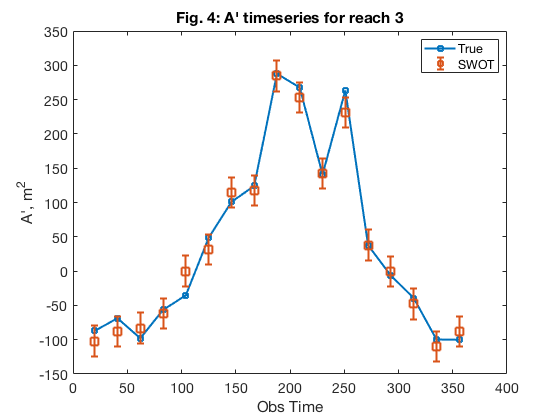

for i=1:nObs
    [dAhat(i),What(i),Hhat(i),dAunc(i)] = CalculatedAEIV(Hobs(r,i),Wobs(r,i),xbreak{r},p{r},nReg,dAHbar,stdW^2,stdH^2,m_zz(:,:,r),nObs);
end

figure(4)
plot(tObs,dAtrue(tObs),'s-','LineWidth',2); hold on;
errorbar(tObs,dAhat,dAunc,'s-','LineStyle','none','LineWidth',2,'MarkerSize',10); hold off;
set(gca,'FontSize',14)
xlabel('Obs Time')
ylabel('A'', m^2')
title(['Fig. 4: A'' timeseries for reach ' num2str(r)])
legend('True','SWOT')


Err.AprimeErrStd=std(dAhat-dAtrue(tObs));
Err.AprimeAvgUnc=mean(dAunc);

There are fourteen required data elements that the SDS will need for each reach, assuming three sub-domains:

- The sub-domain boundary values for water surface elevation: $H_{b,j}$ for $j=1, 2, 3,4$

- The sub-domain boundary values for width: $W_{b,j}$ for $j=1, 2, 3,4$

- The covariance matrix of the height and width observations used in the fitting: $s^2_{H}$, $s^2_{W}$, and $s^2_{WH}$ (currently unused; will be used in future for estimate of $A\prime$uncertainty.

- The width and height error standard deviations assumed for the data: $\sigma_H$ and $\sigma_W$

- The number of height-width data points used for the computations, $N_{obs}$ (currently unused; will be used in future for estimate of $A\prime$uncertainty).

These would be provided by the Science Team via the a priori database.

Performance evaluation should be on the standard deviation of the error compared with the true $A \prime$.

Err.AprimeErrStd=std(dAhat-dAtrue(tObs));
Err.AprimeAvgUnc=mean(dAunc);

## 8. Taking a quick look at the constrained widths and heights

The constraint in equation (6) improves the performance of both the heights and widths. For example, the scatterplot in Fig. 5 shows the raw observations and the constrained widths plotted on the 1:1. The error standard devations are shown written to screen. Generally, we reduce the width standard deviation significantly; there is larger reduction for the cases where there is less variability in widths (e.g. reach 2, where width excluding outliers varies from 130-150 m). The height errors are not much, if at all, decreased, in this case. However, in other cases, we can expect the height errors to improve more than width errors, depending on the relative variability and uncertainty of each.

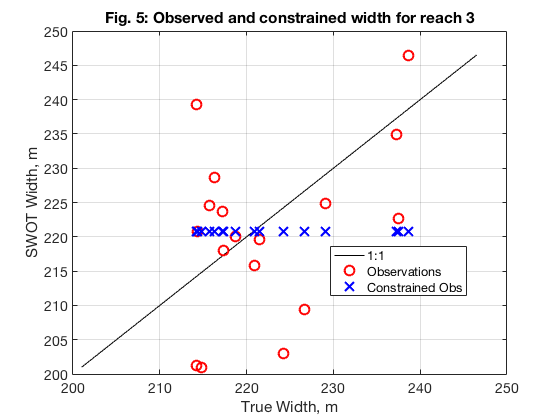

figure(5)

plot([min(Wobs(r,~iout{r})) max(Wobs(r,~iout{r}))],[min(Wobs(r,~iout{r})) max(Wobs(r,~iout{r}))],'k-'); 
hold on;
plot(R.W(r,tObs(~iout{r})),Wobs(r,~iout{r}),'ro','LineWidth',2,'MarkerSize',10); 
plot(R.W(r,tObs(~iout{r})),What(~iout{r}),'bx','LineWidth',2,'MarkerSize',10); 
hold off
set(gca,'FontSize',14)
xlabel('True Width, m')
ylabel('SWOT Width, m')
legend('1:1','Observations','Constrained Obs','Location','Best')
title(['Fig. 5: Observed and constrained width for reach ' num2str(r)])
grid on;



Err.WidthObsStdDev=std(R.W(r,tObs(~iout{r}))-Wobs(r,~iout{r})); %close to stdW
Err.WidthConstrainedStdDev=std(R.W(r,tObs(~iout{r}))-What(~iout{r})); 
Err.HeightObsStdDev=std(R.H(r,tObs(~iout{r}))-Hobs(r,~iout{r})); %close to stdW
Err.HeightConstrainedStdDev=std(R.H(r,tObs(~iout{r}))-Hhat(~iout{r})); 


disp(Err)

               AprimeErrStd: 15.9755
               AprimeAvgUnc: 22.0822
             WidthObsStdDev: 12.1164
     WidthConstrainedStdDev: 8.6036
            HeightObsStdDev: 0.0681
    HeightConstrainedStdDev: 0.0681



If these constrained widths and constrained heights are indeed significantly more precise than the observations, it is at least worth considering whether we ought to add them as new data elements to the SWOT data products. The argument for this is in part that nearly all the work for their computation is already being done in order to estimate $A\prime$. It is possible, of course, to do all of this for nodes in addition to reaches. However, this will greatly increase the overall computational effort, and is not currently part of an existing data product.

## 9. References

Durand, M., J. Neal, E. Rodríguez, K. M. Andreadis, L. C. Smith, and Y. Yoon (2014), Estimating reach-averaged discharge for the River Severn from measurements of river water surface elevation and slope, Journal of Hydrology, 511(C), 92–104, doi:10.1016/j.jhydrol.2013.12.050.

Fuller, W. A. (2006), *Measurement Error Models*, Wiley, New Jersey.

## 10. Appendix

The below is as far as I got on computing the uncertainty of $A\prime$. I took a few shortcuts, and someone will likely need to revisit. Shortcut 1: I'm treating the estimate of the slope uncertainty from the appropriate sub-domain as if no constrained estimation is happening. Shortcut 2: I'm assuming that all uncertainty comes from the slope term, and the height observation; I'm neglecting uncertainty in the breakpoint. Shortcut 3: I'm taking the total number of observations and height-width data covariances over the entire domain to do the computation. These shortcuts end up having competing effects; the overall effect is to overestimate uncertainty, so I've applied a blanket 75% multiplier to uncertainty estimates. This will need to be revisited. The uncertainty for the slope with these shortcuts, and assuming that error in height and width are uncorrealted gives you:


$$\sigma^2_{p1}=\frac{1}{N_{obs}-1} \frac{m^2_{XX}\sigma_{vv}^2+\sigma_{uu}^2\sigma_{vv}^2}{m_{XX}^4} \qquad(A1)$$


where $\sigma^2_{uv}=-p_1\sigma_{uu}^2$, and $\sigma_{vv}^2=\sigma_{ee}^2+p_1^2 \sigma_{uu}^2$, $r=\sigma_{uv}^2 \sigma_{vv}^{-2}$and $m_{XX}^2=r^2(\sigma_W^2-s_W^2)-2(1+p_1 r)rs_{WH}^2+(1+p_1r)^2(\sigma_H^2-s_H^2)$, where $s^2_H$ is the variance of the height measurements used to do the fitting of the relationship, and similar definitions apply to the width measurements, and the width-height covariance. Note that this is written slightly different in Fuller. Then the estimate of the error variance I'm using is derived by computing the variance of the last term on the RHS of equation (7). The result is somewhat unsatisfactory, especially for points far from the sub-domain boundaries. The current expression is:


$$\sigma_{A\prime}^2=\frac{\sigma_{p1}^2}{4}(\hat{H}_t^2-H_{b,d}^2)^2+\frac{p_{1}^2}{4} \sigma_H^2 \qquad (A2)$$
